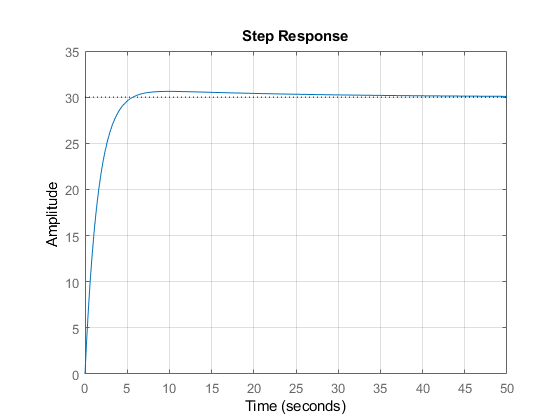

m = 1200;
b = 35;
r = 30;

Kp = 789;
Ki = 39;
Kd = 0;

t = 0:0.1:50;

s = tf('s');
C = pid(Kp,Ki,Kd);
P_cruise = 1/(m*s + b);
T = feedback(C*P_cruise,1);
CruiseControlSystem  = r*T;

figure('Name','Cruise Control','NumberTitle','off');
step(CruiseControlSystem ,t)
axis([0 50 0 r+5])
grid on; grid minor;

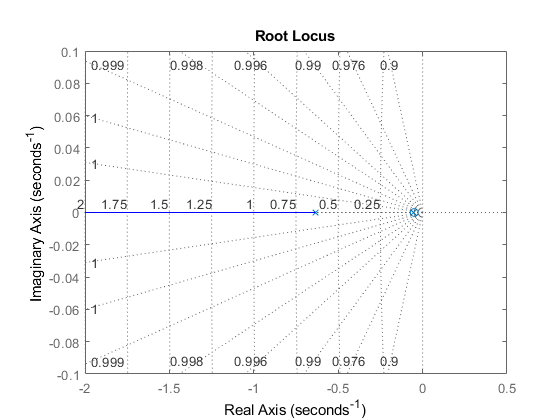


figure('Name','Cruise Control','NumberTitle','off');
rlocus(CruiseControlSystem)
grid on; grid minor;


CruiseControlSystem

CruiseControlSystem =
 
     23670 s + 1170
  ---------------------
  1200 s^2 + 824 s + 39
 
Continuous-time transfer function.

